# downsampling


input_path="Default";% input the folder your image in 
downsample_path="downsample";% input a folder your downsample image to save
downsample_factor=0.5;% adjust the downsample factor, samller means smaller file and lower resolution

data_downsampling(input_path,downsample_path,downsample_factor)

所有 TIFF 图像已处理并保存完毕。


## data_readin as timetable

TimeStep=seconds(0.5);% adjust duration time between two frame
path=downsample_path;
imageTimetable=data_readin(path,TimeStep)

imageTimetable = 619×1 timetable
    Times        imageStack    
    _____    __________________

    0秒      {1024×1024 uint16}
    0.5秒    {1024×1024 uint16}
    1秒      {1024×1024 uint16}
    1.5秒    {1024×1024 uint16}
    2秒      {1024×1024 uint16}
    2.5秒    {1024×1024 uint16}
    3秒      {1024×1024 uint16}
    3.5秒    {1024×1024 uint16}
    4秒      {1024×1024 uint16}
    4.5秒    {1024×1024 uint16}
    5秒      {1024×1024 uint16}
    5.5秒    {1024×1024 uint16}
    6秒      {1024×1024 uint16}
    6.5秒    {1024×1024 uint16}
    7秒      {1024×1024 uint16}
    7.5秒    {1024×1024 uint16}


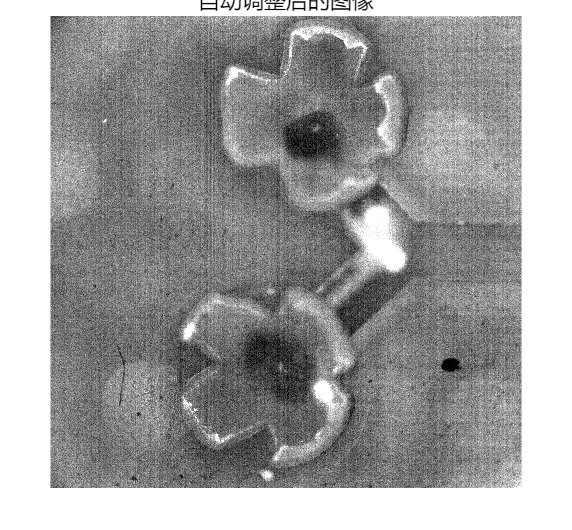

imageshow_auto_adjust(imageTimetable.imageStack{1})

## extract eye mask and orientation

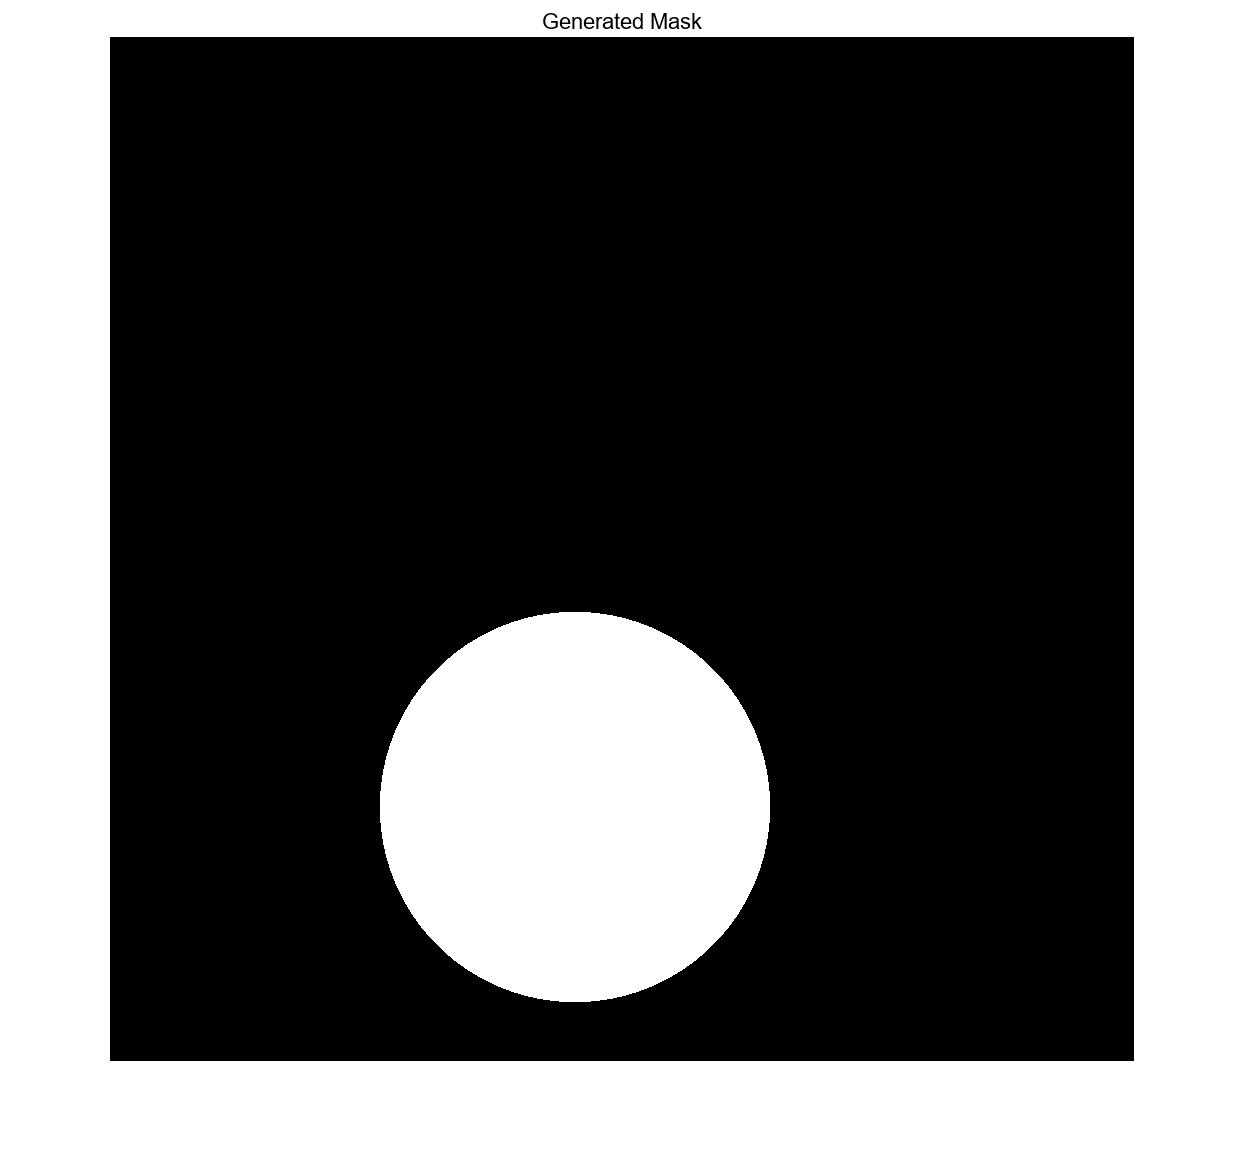

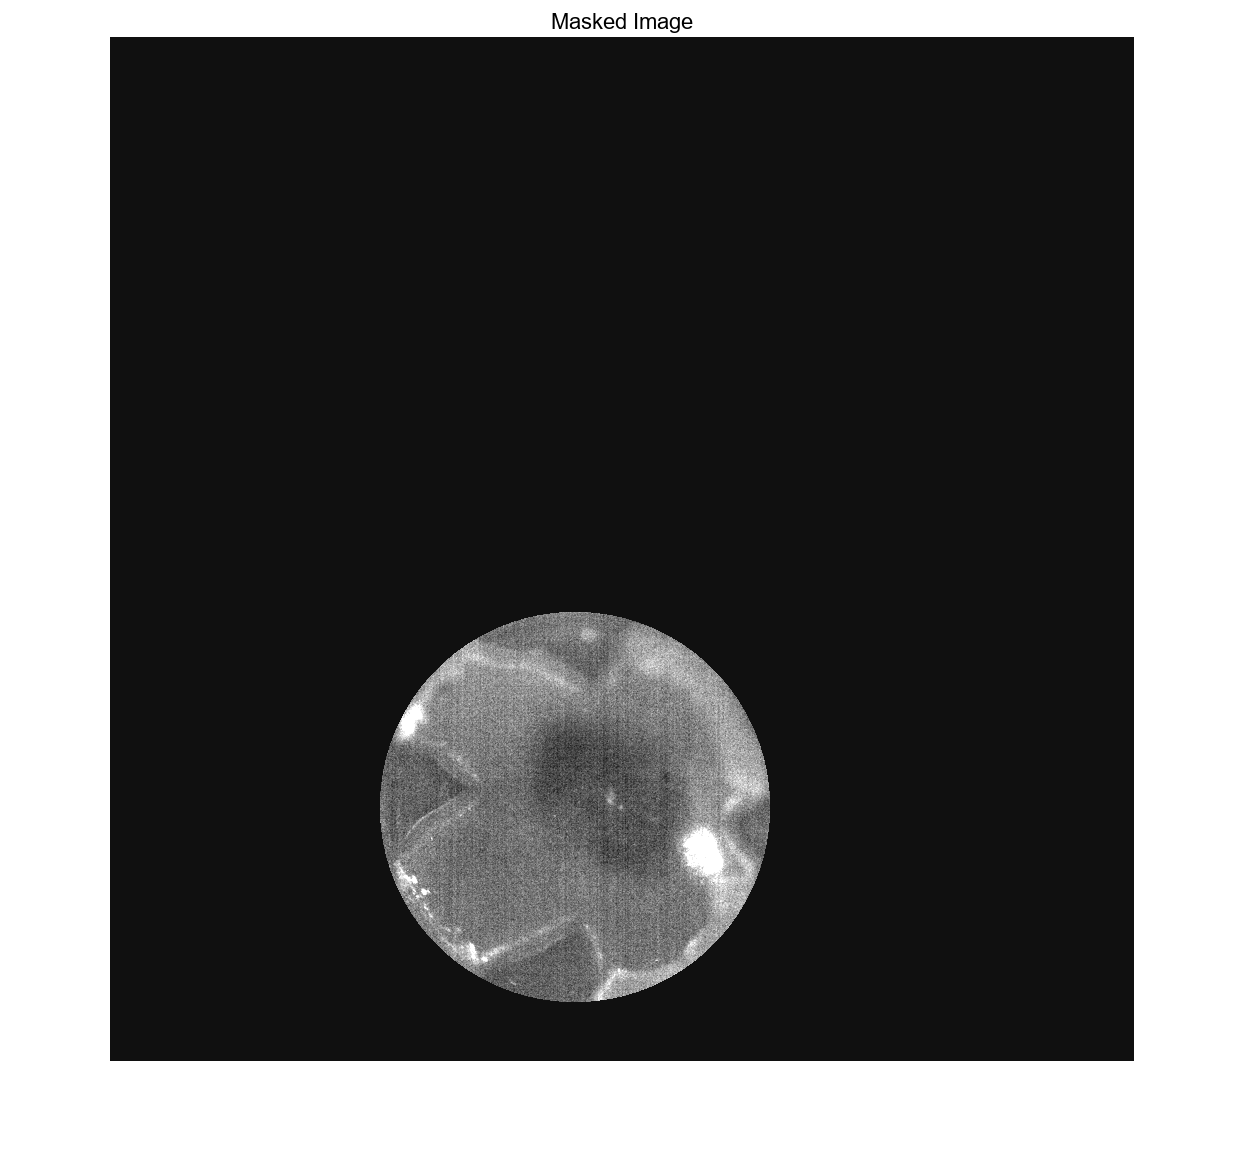

mask_right_eye=get_a_mask_retina(imageTimetable.imageStack{1},"right eye");

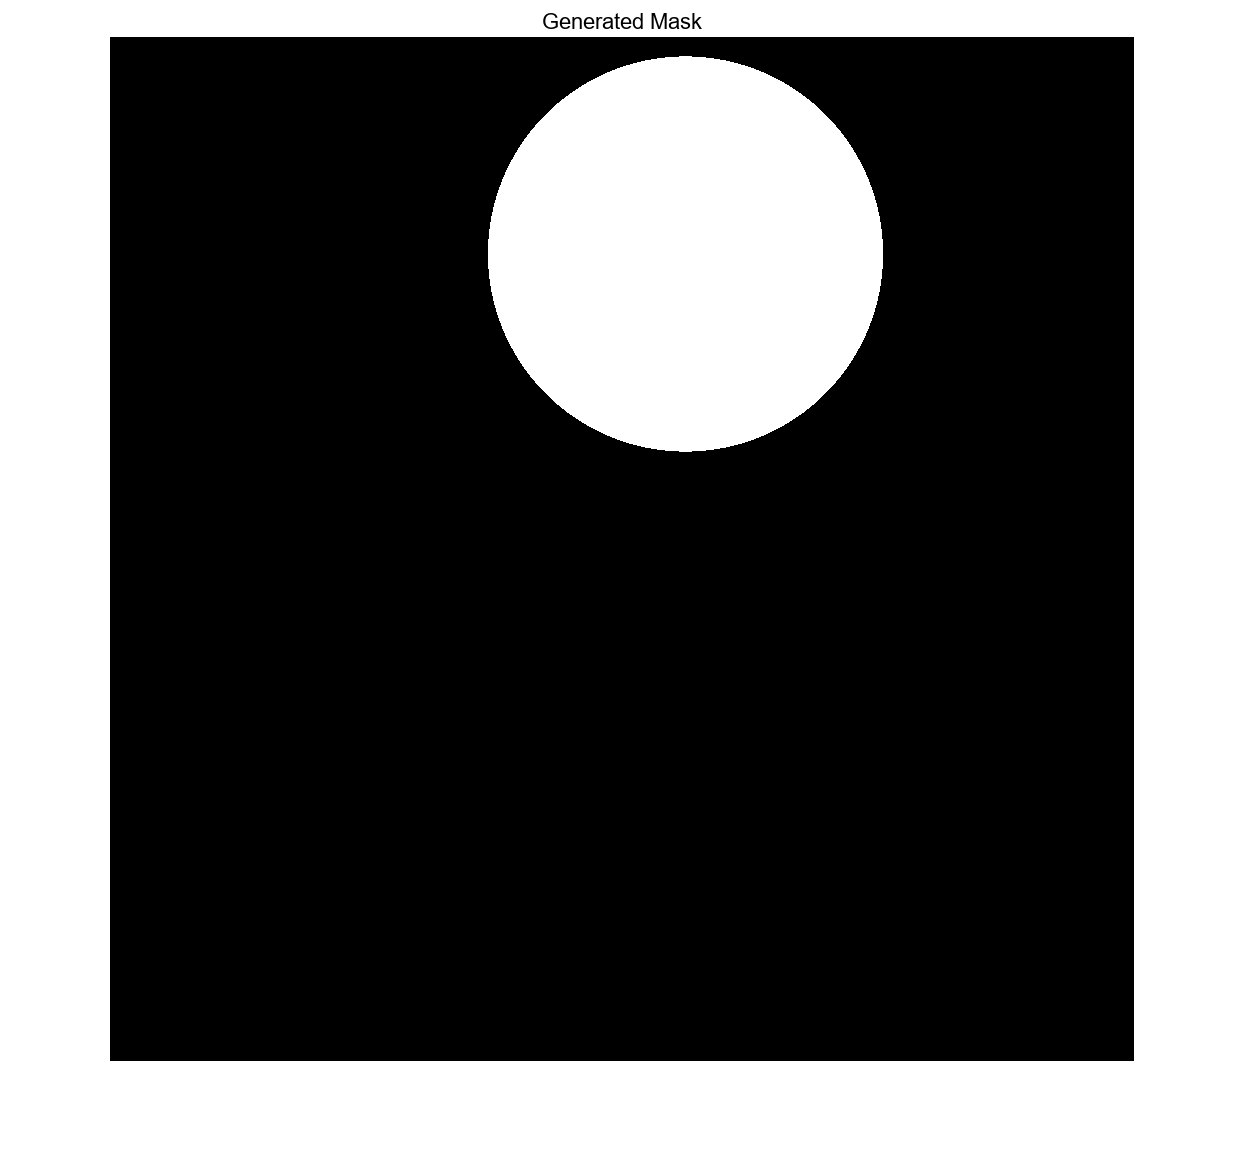

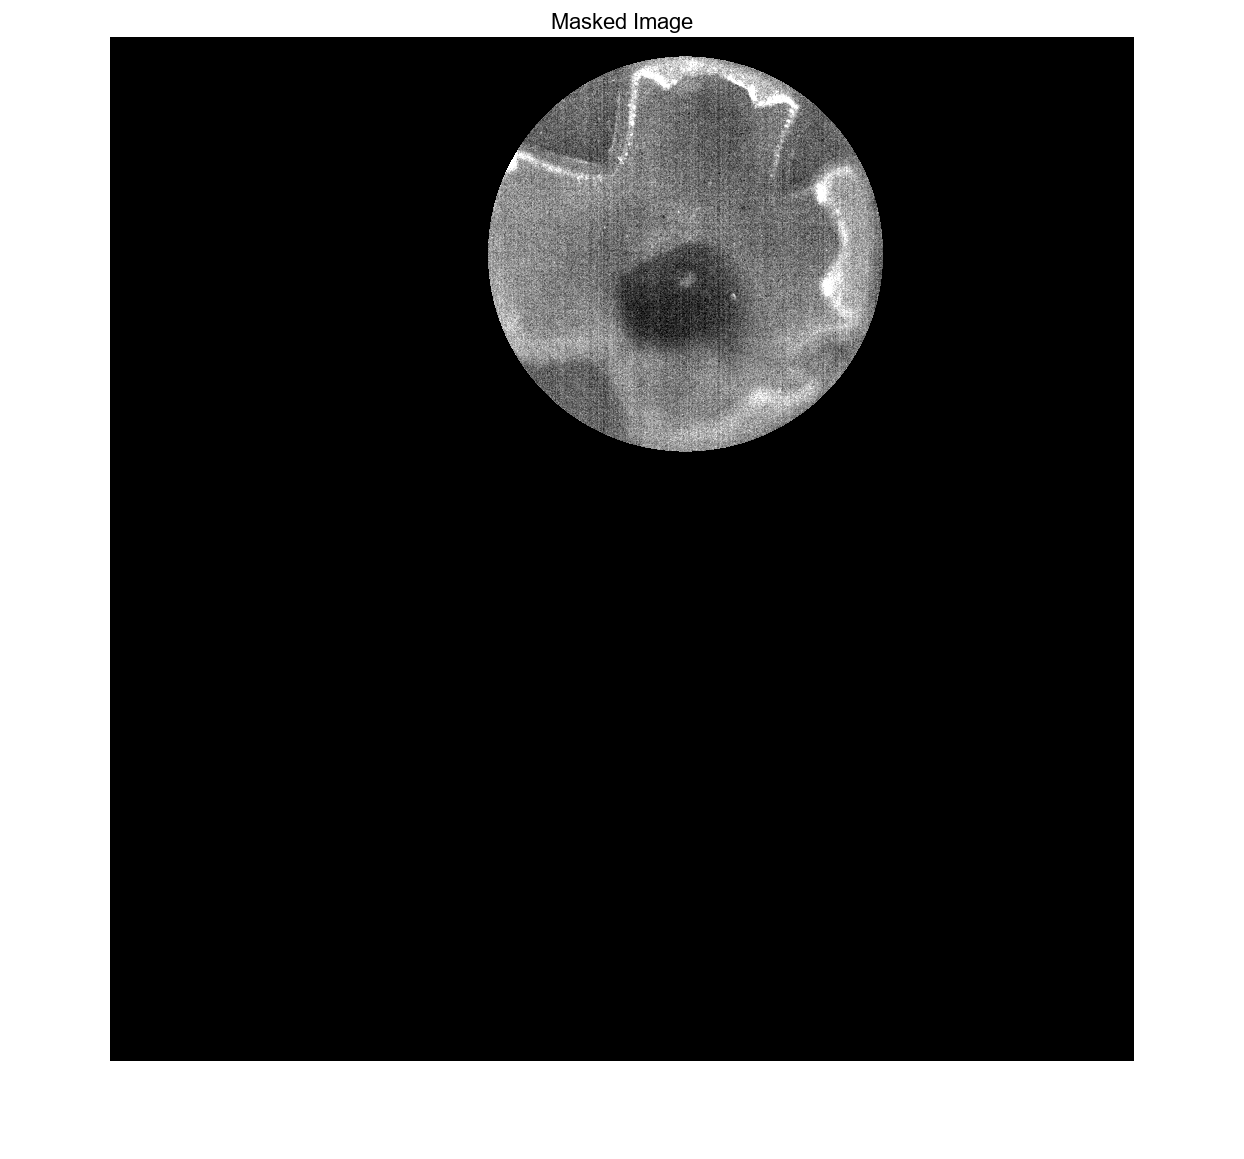

mask_left_eye=get_a_mask_retina(imageTimetable.imageStack{1},"left eye");

请在图像上点击两次以画一条直线：
第一次点击确定圆心，第二次点击确定鼻侧。
存储的直线信息：
    start_point: [492 758]
      end_point: [636 869]



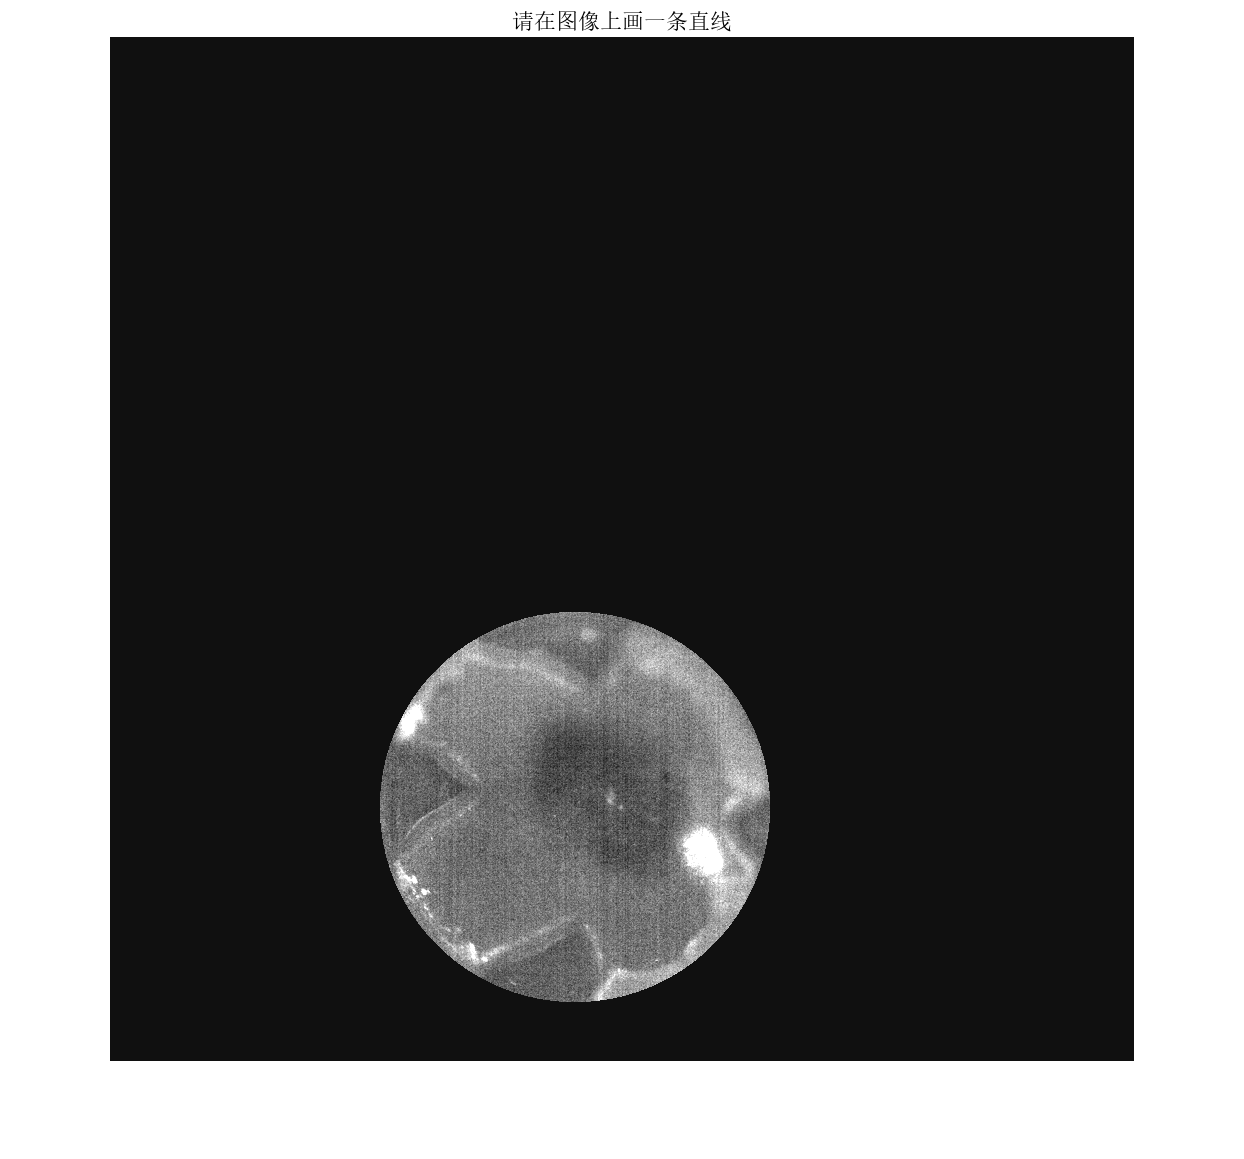

nasal_vector_of_right_eye=get_nasal_orientation(imageTimetable.imageStack{1},mask_right_eye);

请在图像上点击两次以画一条直线：
第一次点击确定圆心，第二次点击确定鼻侧。
存储的直线信息：
    start_point: [577 246.0000]
      end_point: [719.0000 353.0000]



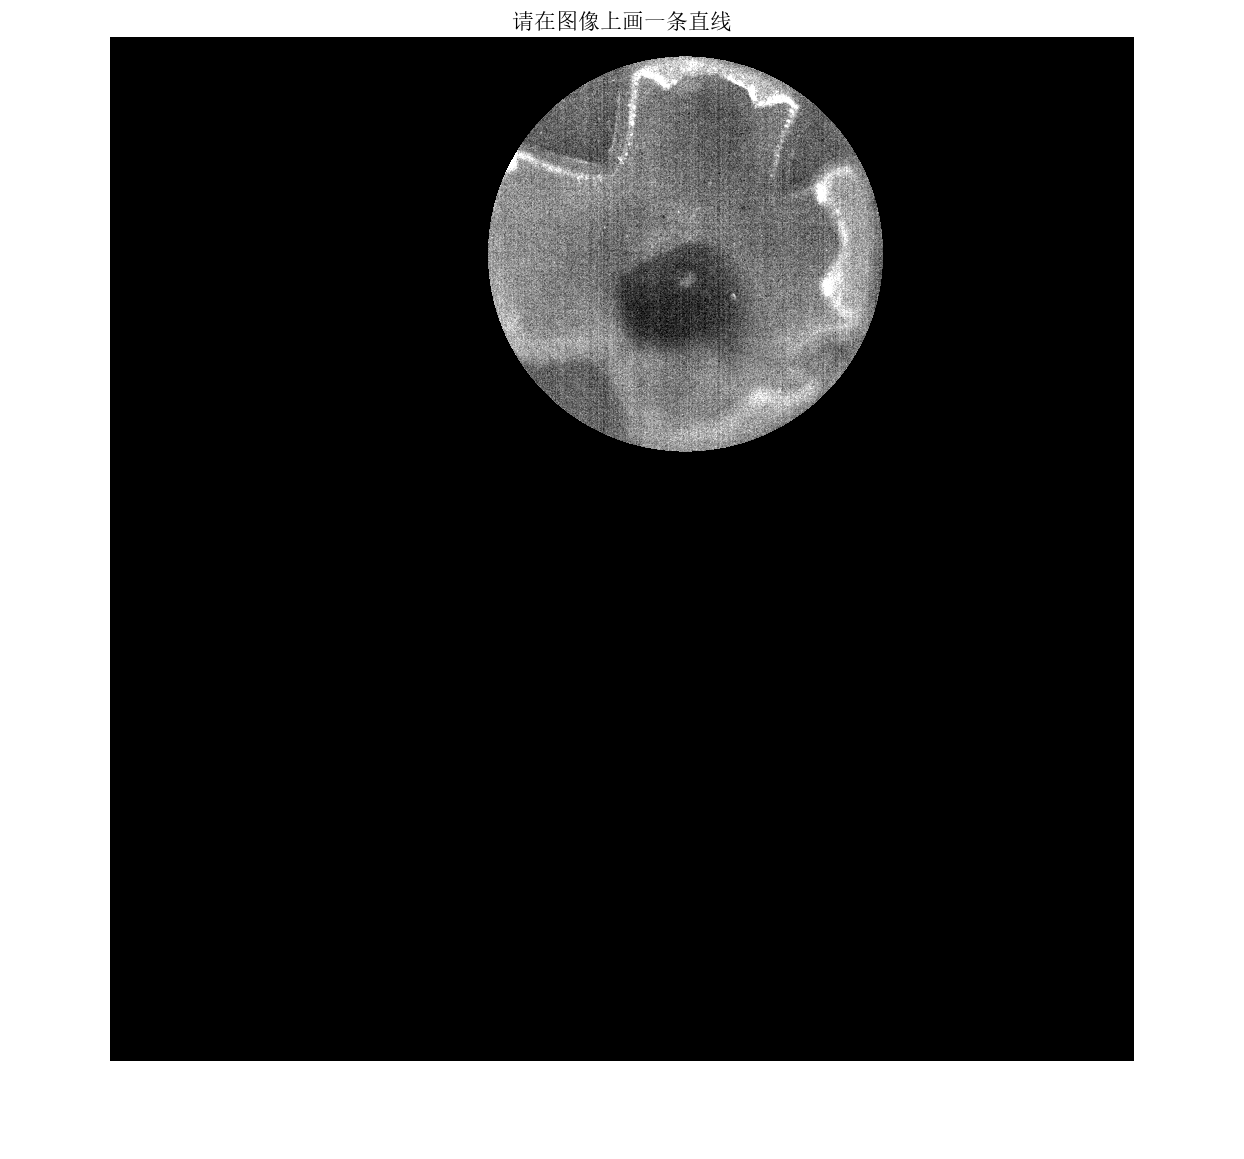

nasal_vector_of_left_eye=get_nasal_orientation(imageTimetable.imageStack{1},mask_left_eye);

radius_of_right_eye=sqrt(length(find(mask_right_eye)));
radius_of_left_eye=sqrt(length(find(mask_left_eye)));


## get mask polar coordinate

vector_right=nasal_vector_of_right_eye.end_point-nasal_vector_of_right_eye.start_point;
[polarData_right,coordinate_right]=transfer_mask_to_polar_coordinate(mask_right_eye,vector_right,nasal_vector_of_right_eye.start_point);
vector_left=nasal_vector_of_left_eye.end_point-nasal_vector_of_left_eye.start_point;
[polarData_left,coordinate_left]=transfer_mask_to_polar_coordinate(mask_left_eye,vector_left,nasal_vector_of_left_eye.start_point);

## get masked data

imageTimetable = addMaskedDataToTimetable(imageTimetable,mask_left_eye,"left")

imageTimetable = 619×2 timetable
    Times        imageStack         leftmasked_data 
    _____    __________________    _________________

    0秒      {1024×1024 uint16}    {122656×1 uint16}
    0.5秒    {1024×1024 uint16}    {122656×1 uint16}
    1秒      {1024×1024 uint16}    {122656×1 uint16}
    1.5秒    {1024×1024 uint16}    {122656×1 uint16}
    2秒      {1024×1024 uint16}    {122656×1 uint16}
    2.5秒    {1024×1024 uint16}    {122656×1 uint16}
    3秒      {1024×1024 uint16}    {122656×1 uint16}
    3.5秒    {1024×1024 uint16}    {122656×1 uint16}
    4秒      {1024×1024 uint16}    {122656×1 uint16}
    4.5秒    {1024×1024 uint16}    {122656×1 uint16}
    5秒      {1024×1024 uint16}    {122656×1 uint16}
    5.5秒    {1024×1024 uint16}    {122656×1 uint16}
    6秒      {1024×1024 uint16}    {122656×1 uint16}
    6.5秒    {1024×1024 uint16}    {122656×1 uint16}
    7秒      {1024×1024 uint16}    {122656×1 uint16}
    7.5秒    {1024×1024 uint16}    {122656×1 uint16}


imageTimetable = addMaskedDataToTimetable(imageTimetable,mask_right_eye,"right")

imageTimetable = 619×3 timetable
    Times        imageStack         leftmasked_data     rightmasked_data 
    _____    __________________    _________________    _________________

    0秒      {1024×1024 uint16}    {122656×1 uint16}    {119624×1 uint16}
    0.5秒    {1024×1024 uint16}    {122656×1 uint16}    {119624×1 uint16}
    1秒      {1024×1024 uint16}    {122656×1 uint16}    {119624×1 uint16}
    1.5秒    {1024×1024 uint16}    {122656×1 uint16}    {119624×1 uint16}
    2秒      {1024×1024 uint16}    {122656×1 uint16}    {119624×1 uint16}
    2.5秒    {1024×1024 uint16}    {122656×1 uint16}    {119624×1 uint16}
    3秒      {1024×1024 uint16}    {122656×1 uint16}    {119624×1 uint16}
    3.5秒    {1024×1024 uint16}    {122656×1 uint16}    {119624×1 uint16}
    4秒      {1024×1024 uint16}    {122656×1 uint16}    {119624×1 uint16}
    4.5秒    {1024×1024 uint16}    {122656×1 uint16}    {119624×1 uint16}
    5秒      {1024×1024 uint16}    {122656×1 uint16}    {119624×1 uint16}
    5.5秒    {10

## get delta F

threhold=0.025;
imageTimetable = calculateDeltaF(imageTimetable,"leftmasked_data", 25,threhold);
imageTimetable = calculateDeltaF(imageTimetable,"rightmasked_data", 25,threhold);
imageTimetable=extract_excitation_mask(imageTimetable,coordinate_left,'leftmasked_deltaF');
imageTimetable=extract_excitation_mask(imageTimetable,coordinate_right,'rightmasked_deltaF');
close_size=10;
imageTimetable=excitation_mask_combine(imageTimetable,'left_excitation_mask',close_size);
imageTimetable=excitation_mask_combine(imageTimetable,'right_excitation_mask',close_size);

## spilt mask too far

imageTimetable=spilt_mask(imageTimetable,'left_closed_mask');

错误使用  . 
无法识别表变量名称 'left_closed_mask'。

出错 spilt_mask (第 5 行)
    closedMask_sheet = imageTimetable.(mask_name);

imageTimetable=spilt_mask(imageTimetable,'right_closed_mask');

## get size and coordinate

imageTimetable=calculate_size_coordinate(imageTimetable,'left_closed_spilt_mask',nasal_vector_of_left_eye,"L");

函数或变量 'nasal_vector_of_left_eye' 无法识别。

imageTimetable=calculate_size_coordinate(imageTimetable,'right_closed_spilt_mask',nasal_vector_of_right_eye,"R");


## visionlize

visionlize(imageTimetable,radius_of_right_eye,'right_size_coordinate');

函数或变量 'radius_of_right_eye' 无法识别。

visionlize(imageTimetable,radius_of_left_eye,'left_size_coordinate');